Филимонов Степан РЛ6-31

Лабарататорная номер 2

Задача:

Написать m-функцию **EnergyFrequency(meff, L, n)**, возращающую значение n-ого *энергетического уровня En (meV) и соответствующей угловой частоты wn (rad*s^-1)* для электрона в зоне проводимости полупроводника (с заданной относительной массой meff) в прямоугольникой бесконечно глубокой потенциальной яме ширины L(нм). Все необходимые для расчета константы загрузить из из созданного mat-файла. Вывести в консоль полученные значения En_meV и wn.

Написать анонимную функцию **deltaEnergy = @(meff, L, n)**, возращающую разность *значений энерии n-го и (n+1)-го* энергетических уровней(meV).

Написать анонимную функцию **Lmax = @(meff, T)** для оценки размеров ямы (нм) в слоистых квантоворазмерных гетероструктурах, обусловленных требованием $\Delta E_{\textrm{nm}} \gg k_B T$.

Фото задания 1:

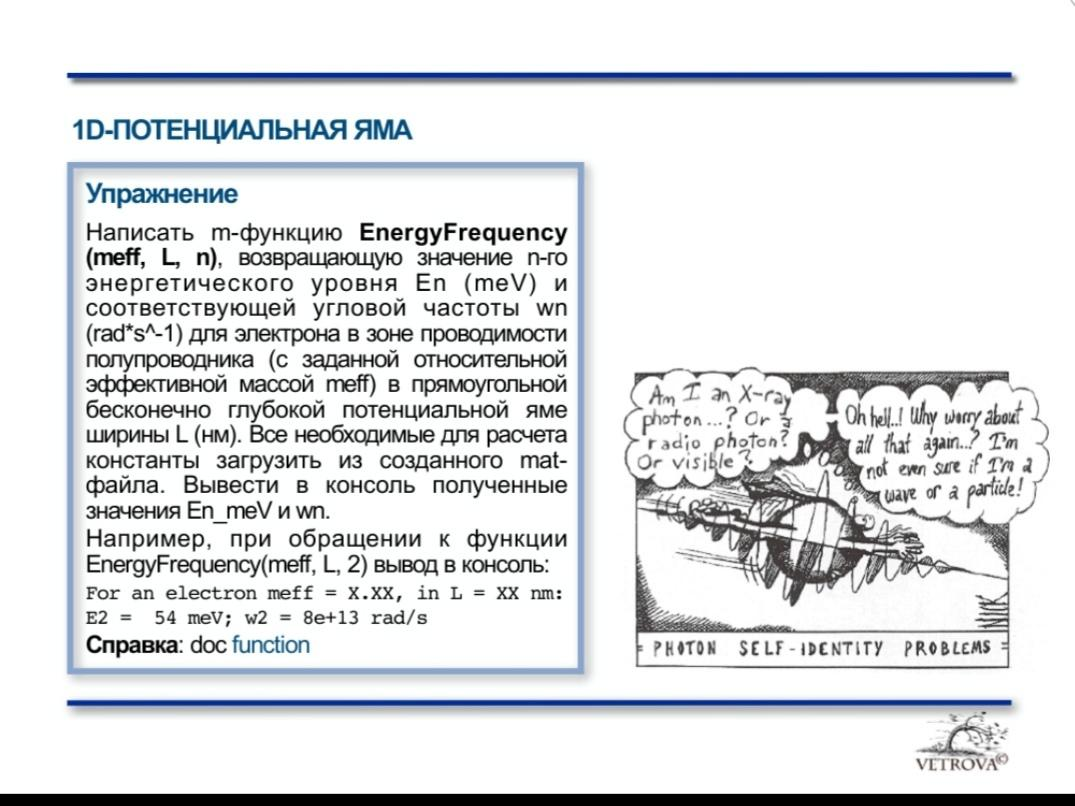

Фото задания 2:

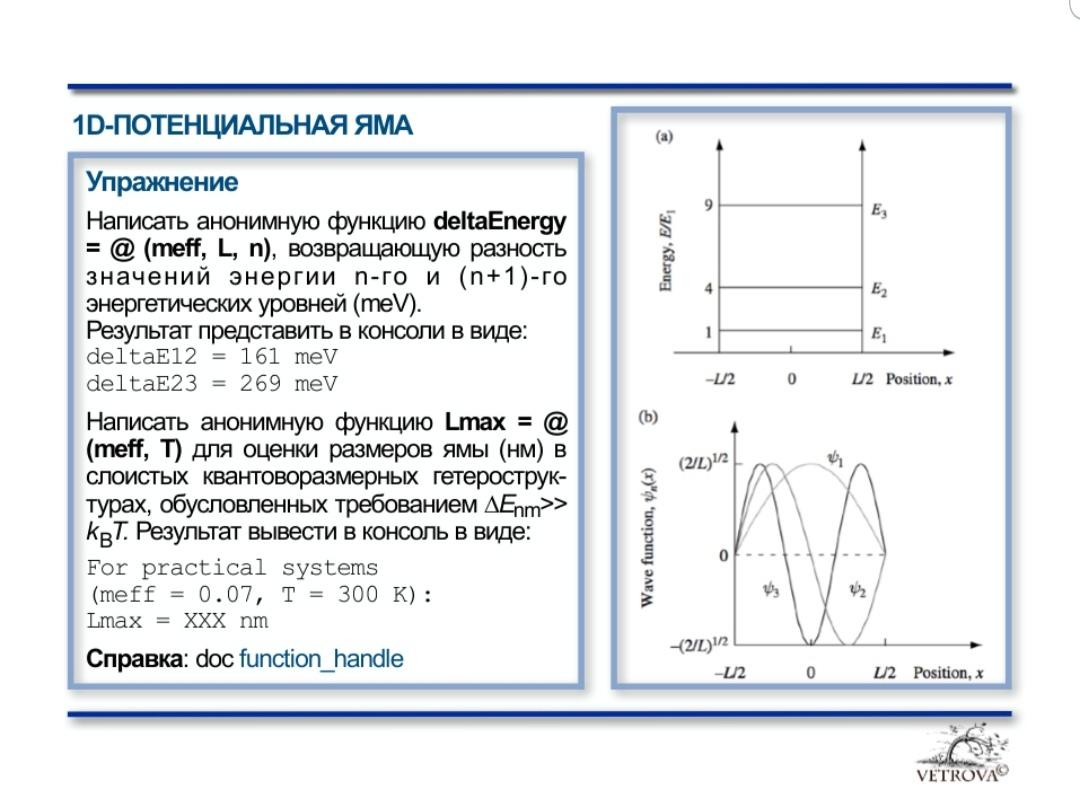

Теория:

**Энергетический уровень** — собственные значения энергии квантовых систем, то есть систем, состоящих из микрочастиц и подчиняющихся законам квантовой механики. Каждый уровень характеризуется определённым состоянием системы, или подмножеством таковых в случае вырождения. Разница между энергетическими уровнями определяет частоту кванта света, выделяемого или поглощаемого при переходе. 

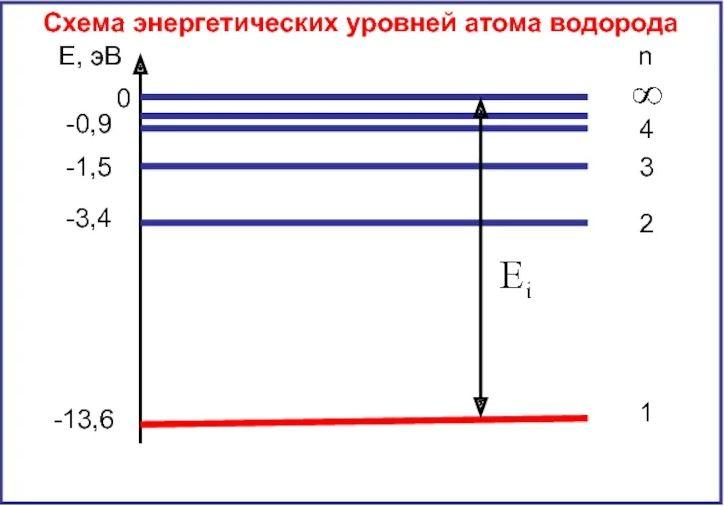

**Потенциальная яма** — область пространства, где присутствует локальный минимум потенциальной энергии частицы. 

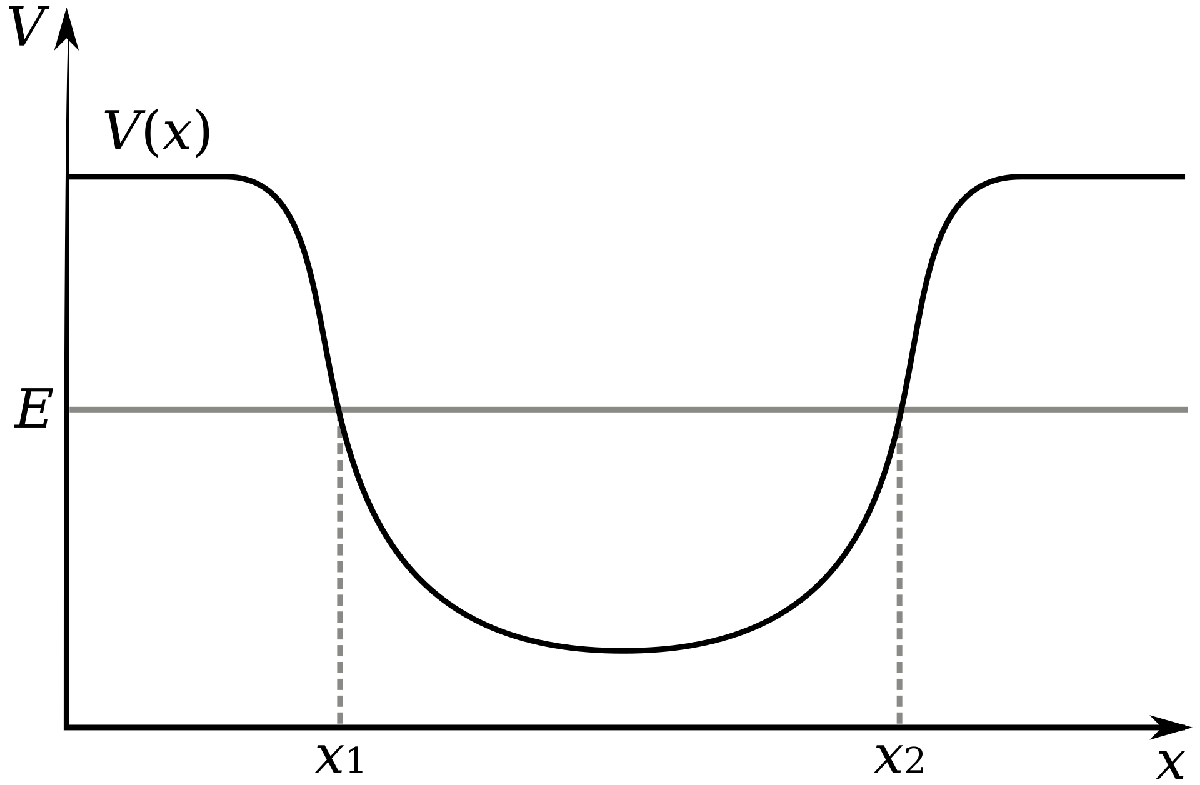

Решение первого задания:

Энергию состояния, описываемого волновой функцией $\psi_n =C_n \sin \left(n\frac{\pi x}{L}\right)$, получим подставив $k_n =n\frac{\pi }{L}$ в $E=\frac{\hbar }{2m}k^2$:

                                                 
$$E_n =\frac{n^2 \hbar^2 \pi^2 }{2mL^2 }$$


,где *n* - номер орбитали, $\hbar$ - постоянная Планка-Дирка, *m* - масса частицы ( по условию $m=\textrm{meff}*m_0$, *L* - ширина потенциальной ямы(нм).

Угловая частота равна:

                                                    
$$\omega_n =\frac{E_n }{\hbar }$$


Решение второго задания:

$\Delta E=E_{n+1} -E_n$.

  $E_n =\frac{n^2 \hbar^2 \pi^2 }{2mL^2 }$; $\mathrm{kL}=\pi n$(плотность состояния) из этого следует, что ${\Delta E}_{n,n+1} =\frac{\hbar^2 \pi^2 }{2mL^2 }\left({\left(n+1\right)}^2 -n^2 \right)=\mathrm{kT}$, $\left({\left(n+1\right)}^2 -n^2 \right)$ = 3, т.к. n = 1. Тогда


$$L=\hbar \pi \sqrt{\frac{3}{2m*k*T}}$$


Код матлаба:

- Основная часть первого задания:

EnergyFrequncy(0.07, 20, 1:3);

For an electrton meff = 0.07, in L = 20 nm\n
E1 =  13 meV;w1 = 1e+35 rad/s
E2 =  54 meV;w2 = 5e+35 rad/s
E3 = 121 meV;w3 = 1e+36 rad/s


EnergyFrequncy(0.07, 10, 1:3);

For an electrton meff = 0.07, in L = 10 nm\n
E1 =  54 meV;w1 = 5e+35 rad/s
E2 = 215 meV;w2 = 2e+36 rad/s
E3 = 483 meV;w3 = 5e+36 rad/s


- Основная часть второго задания:

deltaEnergy = @(meff, L, n) EnergyFrequncy(meff, L, n + 1) - EnergyFrequncy(meff, L, n);
n1 = 1:2;
fprintf('deltaE%li%li = %3i meV\n',[n1; n1 + 1; round(deltaEnergy(0.07, 10, n1))]);

For an electrton meff = 0.07, in L = 10 nm\n
E2 = 215 meV;w2 = 2e+36 rad/s
E3 = 483 meV;w3 = 5e+36 rad/s
For an electrton meff = 0.07, in L = 10 nm\n
E1 =  54 meV;w1 = 5e+35 rad/s
E2 = 215 meV;w2 = 2e+36 rad/s
deltaE12 = 161 meV
deltaE23 = 269 meV


load('constans.mat',"hbar","m0","eV2J","kB");
Lmax = @(meff, T) sqrt(3/(2*meff*m0*kB*T*eV2J))*(pi*hbar)*1e9;
meff1 = 0.07; T1 = 300;
fprintf('For practical systems (meff = %3.2f, T = %3i K):\n Lmax = %2i nm\n',meff1,T1,round(Lmax(meff1,T1)))

For practical systems (meff = 0.07, T = 300 K):
 Lmax = 25 nm


datetime('now')

ans = datetime
   16-Oct-2021 23:12:33


- Функция:

function [En, wn] = EnergyFrequncy(meff, L_nm, n)
  disp(['For an electrton meff = ',num2str(meff),', in L = ', num2str(L_nm),' nm\n']);
  load('constans.mat',"hbar","m0","J2eV");
  En = (n * pi *hbar/(L_nm * 1e-9)).^2 ./ (2 * meff * m0);
  En = En * J2eV * 1e3;
  wn = En / hbar;
  fprintf('E%1i = %3i meV;w%1i = %1.0e rad/s\n',[n;round(En);n;wn]);
end